
clear
n = 59;  % Número de pisos
omega_cons = 2 * pi / 1;  % Frecuencia del sismo, supongamos un periodo de 2 segundos
E = 0.062;  % Amplitud del sismo

npisos = 59;
ms = ones(1,npisos) * 640500; %[m1, m2, m3]
ks = ones(1,npisos) * 667000;

Msim = diag(ms);  % Matriz de masas diagonal
Ksim = zeros(npisos, npisos);

Ksim(1,1) = ks(1) + ks(2);
Ksim(1,2) = -ks(2);
for i = 2:npisos-1
    Ksim(i,i-1) = -ks(i);
    Ksim(i,i) = ks(i) + ks(i+1);
    Ksim(i,i+1) = -ks(i+1);
end
Ksim(npisos, npisos-1) = -ks(npisos);
Ksim(npisos, npisos) = ks(npisos);

A_num = -inv(Msim) * Ksim;


function dydt = sistemaResorte(t, y, A, b, omega, E)
    x = y(1:n);
    v = y(n+1:end);
    a = A * x + E * omega^2 * cos(omega * t) * b;  
    dydt = [v; a];
end

% Tiempo de simulación
tspan = [0 5];  % Intervalo de tiempo para la simulación

% Condiciones iniciales
x0 = zeros(n, 1);  % Desplazamiento inicial
v0 = ones(n, 1)*0.1;  % Velocidad inicial
initial_conditions = [x0; v0];

% Vector de fuerzas externas por unidad de masa (sismo)
b = ones(n, 1);  % Vector unitario si todos los pisos se ven igualmente afectados

% Resolver la ecuación diferencial no homogénea
[eigenvector,eigenvalor] = eig(A_num)

eigenvector =     0.0097   -0.0193   -0.0289    0.0384    0.0478   -0.0571   -0.0662    0.0752    0.0839   -0.0924   -0.1006    0.1085    0.1162   -0.1235   -0.1305    0.1371    0.1433   -0.1492   -0.1546    0.1596    0.1641   -0.1682   -0.1718    0.1750    0.1776   -0.1798   -0.1814    0.1826    0.1832   -0.1833   -0.1829    0.1820    0.1806   -0.1787   -0.1763    0.1734    0.1701   -0.1662   -0.1619    0.1571    0.1519   -0.1463   -0.1403    0.1338    0.1270   -0.1199   -0.1124    0.1046    0.0965   -0.0882
   -0.0193    0.0384    0.0571   -0.0752   -0.0924    0.1085    0.1235   -0.1371   -0.1492    0.1596    0.1682   -0.1750   -0.1798    0.1826    0.1833   -0.1820   -0.1787    0.1734    0.1662   -0.1571   -0.1463    0.1338    0.1199   -0.1046   -0.0882    0.0707    0.0525   -0.0337   -0.0145   -0.0048   -0.0241    0.0432    0.0617   -0.0795   -0.0965    0.1124    0.1270   -0.1403   -0.1519    0.1619    0.1701   -0.1763   -0.1806    0.1829    0.1832   -0.1814   -0.1776    0.1718    0

eigenvalor =    -4.1626         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0   -4.1539         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

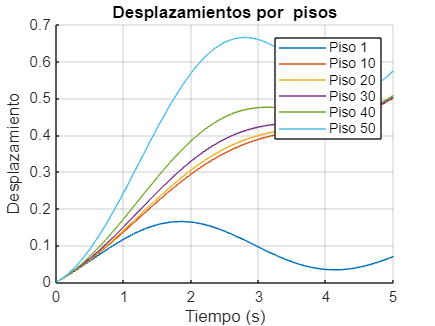

omega_fn = sqrt(-eigenvalor);
E_num = diag(diag(sqrt(x0 + (v0./omega_fn).^2 )));


[t, y] = ode23s(@(t, y) sistemaResorte(t, y, A_num, b, mean(diag(omega_fn)), E_num), tspan, initial_conditions);

% Extraer desplazamientos
desplazamiento = y(:, 1:n);

% Pisos para graficar
pisos_para_graficar = [1, 10, 20, 30, 40, 50];
figure;
hold on;
for i = 1:length(pisos_para_graficar)
    piso = pisos_para_graficar(i);
    plot(t, desplazamiento(:, piso), 'DisplayName', ['Piso ', num2str(piso)])
end
hold off;
xlabel('Tiempo (s)');
ylabel('Desplazamiento');
title('Desplazamientos por  pisos');
legend show;
grid on;